URL = 'https://ssd.mathworks.com/supportfiles/vision/deeplearning/models/yolov2/tiny_yolov2.tar';
pretrainedNetfile = 'yolov2Tiny.tar';
if ~exist(pretrainedNetfile,'file')
    disp('Downloading pretrained network (58 MB)...');
    websave(pretrainedNetfile,URL);
end




%  extract downloaded Pretrained  files

ONNXfiles = untar(pretrainedNetfile);
pretrainedNet = fullfile('tiny_yolov2', 'Model.onnx');

%Importing the network Layers

lgraph = importONNXLayers(pretrainedNet,'ImportWeights',true);

%removing the regression Layer
lgraph = removeLayers (lgraph,'RegressionLayer_grid');

%Defining the anchor boxes
onnxAnchors = [1.08,1.19; 3.42,4.41; 6.63,11.38; 9.42,5.11; 16.62,10.52];

inputSize = lgraph.Layers(1,1).InputSize(1:2);
lastActivationSize = [13,13];
upScaleFactor = inputSize./lastActivationSize;
anchorBoxesTmp = upScaleFactor.* onnxAnchors;
anchorBoxes = [anchorBoxesTmp(:,2),anchorBoxesTmp(:,1)];

%Reordering the detection Layer Weights

weight =lgraph.Layers(end,1).Weights;
bias = lgraph.Layers(end,1).Bias;
layersName = lgraph.Layers(end,1).Name;
numAnchorBoxes =size(onnxAnchors,1);
[modWeights, modBias] = sortONNXWeights(weight,bias,numAnchorBoxes);

%replacing the weights and bias of the last convolution layer with a new one
filterSize = size(modWeights,[1 2]);
numFilters = size(modWeights,4);
modConvolution8 = convolution2dLayer(filterSize,numFilters,...
    'Name',layersName,'Bias',modBias,'Weights',modWeights);
lgraph = replaceLayer(lgraph,'convolution8',modConvolution8);

%Adding YOLOv2 Transform and Output Layers
classes = tinyYOLOv2Classes;

layersToAdd = [
    yolov2TransformLayer(numAnchorBoxes,'Name','yolov2Transform');
    yolov2OutputLayer(anchorBoxes,'Classes',classes,'Name','yolov2Output');
    ];

lgraph = addLayers(lgraph, layersToAdd);
lgraph = connectLayers(lgraph,layersName,'yolov2Transform');

%remove the 'Elementwise Affine Layer' as it duplicates the preprocessing step by the object detector

yoloScaleLayerIdx = find(...
    arrayfun( @(x)isa(x,'nnet.onnx.layer.ElementwiseAffineLayer'), ...
    lgraph.Layers));

if ~isempty(yoloScaleLayerIdx)
    for i = 1:size(yoloScaleLayerIdx,1)
        layerNames {i} = lgraph.Layers(yoloScaleLayerIdx(i,1),1).Name;
    end
    lgraph = removeLayers(lgraph,layerNames);
    lgraph = connectLayers(lgraph,'image','convolution');
end

%create the  Object Detector
basenetwork =assembleNetwork(lgraph)

basenetwork =   DAGNetwork with properties:

         Layers: [34×1 nnet.cnn.layer.Layer]
    Connections: [33×2 table]
     InputNames: {'image'}
    OutputNames: {'yolov2Output'}


yolov2Detector = yolov2ObjectDetector(basenetwork)

yolov2Detector =   yolov2ObjectDetector with properties:

            ModelName: 'importedNetwork'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [416 416]
          AnchorBoxes: [5×2 double]
           ClassNames: [aeroplane    bicycle    bird    boat    bottle    bus    car    cat    chair    cow    diningtable    dog    horse    motorbike    person    pottedplant    sheep    sofa    train    tvmonitor]


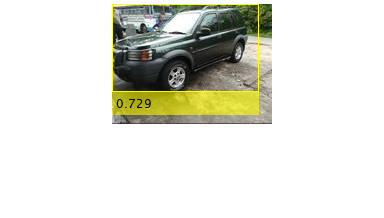

%Detect an Object 
I = imread('IS Object detection Implementation/Vehicle_images/1633889154395_Land Rover Freelander 1999 for sale.jpg');
% Convert image to BGR format.
Ibgr = cat(3,I(:,:,3),I(:,:,2),I(:,:,1));
[bboxes, scores, labels] = detect(yolov2Detector, Ibgr);
detectedImg = insertObjectAnnotation(I, 'rectangle', bboxes, scores);
figure
imshow(detectedImg);

analyzeNetwork(basenetwork)

%FUNCTIONS BELOW


 function [modWeight,modBias] = sortONNXWeights(weights,bias,numAnchorBoxes)
%rearrangeONNXWeights rearranges the weights and biases of an imported YOLO
%v2 network as required by yolov2ObjectDetector.
weightsSize = size(weights);
biasSize = size(bias);
sizeOfPredictions = biasSize(3)/numAnchorBoxes;

% Reshape the weights with regard to the size of the predictions and anchors.
reshapedWeights = reshape(weights,prod(weightsSize(1:3)),sizeOfPredictions,numAnchorBoxes);

% Extract the weights related to IoU, boxes, and classes.
weightsIou = reshapedWeights(:,5,:);
weightsBoxes = reshapedWeights(:,1:4,:);
weightsClasses = reshapedWeights(:,6:end,:);

% Combine the weights of the extracted parameters as required by
% yolov2ObjectDetector.
reorderedWeights = cat(2,weightsIou,weightsBoxes,weightsClasses);
permutedWeights = permute(reorderedWeights,[1 3 2]);

% Reshape the new weights to the original size.
modWeight = reshape(permutedWeights,weightsSize);

% Reshape the biases to the size of the predictions and anchors.
reshapedBias = reshape(bias,sizeOfPredictions,numAnchorBoxes);

% Extract the biases
biasIou = reshapedBias(5,:);
biasBoxes = reshapedBias(1:4,:);
biasClasses = reshapedBias(6:end,:);

% Combine the biases.
reorderedBias = cat(1,biasIou,biasBoxes,biasClasses);
permutedBias = permute(reorderedBias,[2 1]);

% Reshape the new biases to the original size.
modBias = reshape(permutedBias,biasSize);
end


function classes = tinyYOLOv2Classes()
% Return the class names corresponding to the pretrained ONNX tiny YOLO v2
% network.
% classes from the dataset 

classes = [ ...
    " aeroplane", "bicycle", "bird", "boat", "bottle", "bus", "car",...
    "cat", "chair", "cow", "diningtable", "dog", "horse", "motorbike",...
    "person", "pottedplant", "sheep", "sofa", "train", "tvmonitor"];
end

function detector = PretrainedYOLOv2Detector()

pretrained = fullfile('tiny_yolov2', 'Model.onnx'); 
detector = pretrained.detector;
end
